amp = 700 %mv

amp = 700

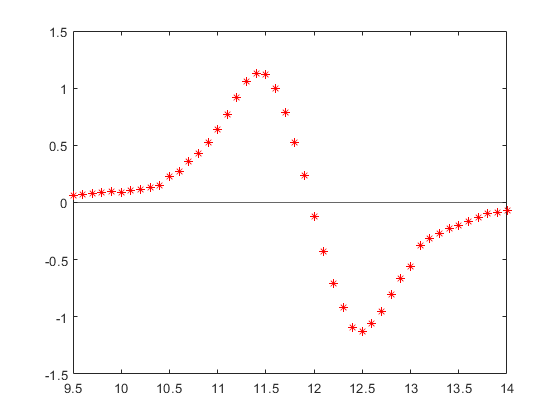

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


R=0.82; %error 10%

v_dc =         [9.5     9.6     9.7   9.8    9.9   10     10.1  10.2    10.3    10.4    10.5    10.6    10.7    10.8    10.9    11      11.1    11.2    11.3    11.4    11.5    11.6    11.7    11.8    11.9    12      12.1    12.2    12.3    12.4    12.5    12.6    12.7    12.8    12.9    13      13.1    13.2    13.3    13.4    13.5,   13.6,   13.7,   13.8,   13.9,   14      ];
I_modulation = [348.51, 350.2, 353.1, 356.3, 390,  402.9, 407,  411.02, 415.15, 419.42, 423.5,  427.55, 434.5,  438.55, 442.6,  446.56, 450.77, 455.29, 459.48, 463.73, 468.18, 472.37, 476.92, 480.95, 486.67, 490.93, 494.65, 498.36, 502.48, 506.8,  511.44, 515.74, 519.63, 524.15, 528.68, 532.55, 487.21, 490.8,  494.35, 497.85, 501.6,  505.1,  508.76, 512.34, 514.37, 517.97  ]/R;
I_m_err =      [0.2,    0.1,   1,     0.5,   0.5,  0.05,  0.05, 0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.5,    0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05,   0.05    ]/R;
phase =        [1       1,     1,     1,     1,    1,     1,    1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      -1,     -1,     -1,     -1,     -1,     -1,     -1,     -1      -1,     -1,     -1,     -1,     -1,     -1,     -1,     -1,     -1,     -1,     -1,     -1,     -1      ];
ptp_Y =        [8.5,    10,    11,    12.3,  13.5, 12.5,  14.8, 16.5,   19,     21,     32,     38,     51,     61,     74,     91,     109,    131,    150,    160,    159,    142,    111.5,  74,     33,     18,     61,     101,    131,    155,    160,    151,    135,    114,    94,     80,     54,     45,     38,     32,     28,     24,     19,     14,     12,     10      ];
ptp_Y_err =    [1,      0.5,   1,     0.5,   1,    1,     1,    1,      0.5,    1,      1,      2,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      1,      3,      2,      2,      2,      2,      3,      2,      3,      2,      2,      2,      3,      2,      1,      1,      1,      1       ];
ptp_X_modulation = [3.09]*length(I_modulation); %err 0.01mv 


plot(v_dc, ptp_Y./ptp_X_modulation.*phase, '*r')
yline(0)